# Geoscience Data Analysis

*D. Hasterok (derrick.hasterok@adelaide.edu.au)*

*Dept. of Earth Sciences, University of Adelaide, North Terrace, Adelaide, SA 5005*

# 8 Multivariate Analysis

clear all;

addpath ../codes
addpath ../data

## 8.1 Visualizing Multivariate Data

### 8.1.1 Introduction

A lot of our data are multivariate as it is increasingly less common to collect one type of data from a sample set for a study.  It is possible to represent multiple dimensions for comparison, think the classic Cartesian plot which allows for 2-dimensional representation of a dataset.

Data of 3-dimensions can be visualized in on a 2-dimensional page as a perspective (or even better as virtual reality using stereo-plotting), as 2-dimensional histograms (heat maps), x-y plot with points of different shapes, sizes or colors, and of course in geochemistry as a ternary diagram.

Data of 4-dimensions can be visualized by combining two of the elements above, e.g., scatter plot with color and size, or shape and color, or shape and size.

But how do we represent 5-dimensions, or 6 or 7 or $N$?  Geochemical data can have 90 dimensions (H through U minus the two non-natural elements).  Enter dimensional reduction techniques.  Dimensional reduction methods are any mathematical techniques that seek to reduce the number of dimensions to those that highlight the greatest differences and/or similarities in the data with the fewer dimensions than the original data.  Dimensional reduction can be performed by removing largely redundant dimensions, or via transformation of the data.

In this chapter, we discuss two-dimensional reduction techniques, principal component analysis (PCA) and multi-dimensional scaling (MDS).  There are some similarities between the two, but the results are sufficiently different.  Be aware that there are a number of other dimensional reduction techniques not discussed (discriminant analysis, factor analysis, etc.).  Depending upon your problem, it may be worthwhile to explore a few of these techniques to find the one that best suits your problem or data.

But before we get to the multidimensional methods, let's look at some ways to visualize multidimensional data, because it is not always necessary to use dimensional reduction to get something out of a multidimensional dataset.  The examples below are by no means the only ones.  We will examine a few additional multidimensional plots in the geochemistry chapter that are not covered here.

### 8.1.2 Heat Map

A heat map is simply a 2-dimensional histogram.  So we have a set of bins in an x and y dimension.

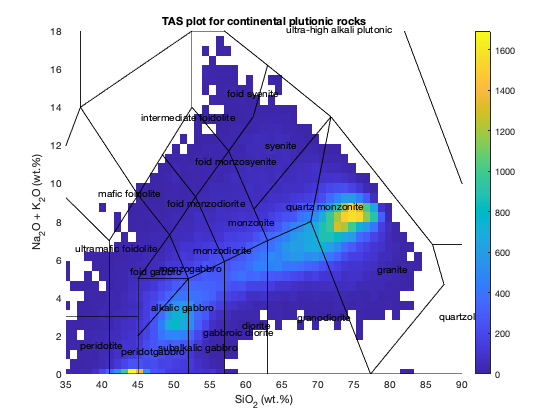

% load plutonic major element geochemistry data
data = readtable('plutonic_geochem.xlsx');

% make a heat map on a total alkali silica plot
S = data.sio2;
TA = data.na2o + data.k2o;

s_ax = [35:1:90];
ta_ax = [0:0.5:18];

figure;
hold on;
n = hist2d(S,TA,s_ax,ta_ax);
imagesc(s_ax,ta_ax,n);
axis xy;
xlabel('SiO_2 (wt.%)');
ylabel('Na_2O + K_2O (wt.%)');
colormap([1 1 1; parula]);
colorbar;

% add TAS fields
tasgons = load_tasgons;
for i = 1:length(tasgons)
    x = tasgons{i,1}(:,1);
    y = tasgons{i,1}(:,2);
    plot(x,y,'k-');
    
    text(mean(x),mean(y),tasgons{i,3});
end
axis([s_ax(1) s_ax(end),ta_ax(1),ta_ax(end)])
set(gca,'Box','on');
title('TAS plot for continental plutionic rocks')

### 8.1.2 Scatter Plot

A scatter plot is simply point by point plot of data.  The points can change size, shape, and color to add additional dimensions or emphasize certain aspects of a dataset.  We have already seen scatter plots used in previous worked examples in this course.

### 8.1.3 Contour/Surface Plots

The difference between a contour plot and a surface plot and other similar plots is how the data are constructed while the underlying data may be the same.  Several methods to produce such plots are shown below.

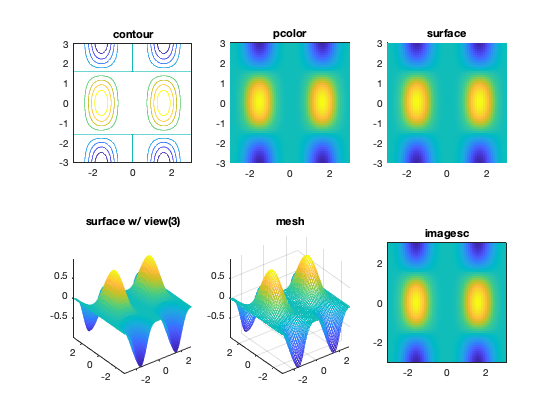

% create a regular spatial grid
[xq,yq] = meshgrid(-3:0.1:3);

% compute values of a periodic function in x and y
v = sin(xq).^4 .* cos(yq);

figure;
subplot(231);
% use contourf to fill the contours much like pcolor and surface, but the
% colors are discretized according to the contour interval. Matlab's
% contouring algorithm is not the best as it will often draw very angular
% contours when the gridding is sparce.
contour(xq,yq,v);
title('contour');
axis tight;
axis equal;

subplot(232);
pcolor(xq,yq,v);
title('pcolor');
shading flat;
axis equal;
axis tight;

subplot(233);
% surface plot
surface(xq,yq,v);
title('surface');
shading flat;
axis tight;
axis equal;

subplot(234);
% view(3) will display a surface plot in 3d, the default is view(2), 2d.
surface(xq,yq,v);
title('surface w/ view(3)');
shading flat;
axis tight;
view(3);

subplot(235);
% creates a wire mesh in 3d
mesh(xq,yq,v);
title('mesh');
axis tight;
shading flat;

subplot(236);
% this method is fastest for the computer, but also the least customizable
% in appearance other than color
imagesc(xq(1,:),yq(:,1),v);
axis xy;
title('imagesc');
axis tight;
axis equal;

### 8.1.4 Radar Plot

A radar plot is a multidimensional plot that produces an axis for each element of a vector extending from the center to the perimeter of an encompassing circle.  Each axis is like the spoke of a wheel, separated by equal angles.  To plot the data, one then connects the value of each point to the value on the adjacent axes.  In the example below, a radar plot is produced to illustrate the changing chemistry of subalkaline plutonic rocks from mafic to felsic compositions.  The result nicely illustrates the decrease in CaO, MgO, and FeO as plutonic rocks become more felsic.

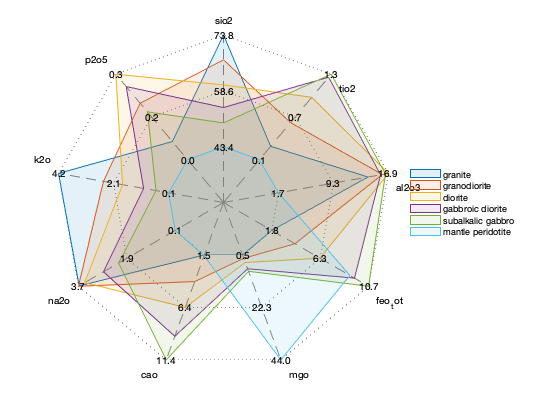

% using the continental plutonic rocks again as the input dataset

% we will examine the pattern of major elements for several common rock
% types
oxides = {'sio2','tio2','al2o3','feo_tot','mgo','cao','na2o','k2o','p2o5'};
rock_types = {'granite','granodiorite','diorite','gabbroic diorite','subalkalic gabbro','mantle peridotite'};

% radarprep simply determines the average chemistry for each rock type
R = radarprep(data,'rock_type',rock_types,oxides);

% create radar plot
figure;
radarplot(R);

## 8.2 Basic Statistics

### 8.2.1 Mean

To compute the mean of a column vector of length $M$,


$$\bar{x} = {\bf 1}^{\text{T}}{\bf x}/M$$


and to compute the mean of a matrix by column with size $(M,N)$,


$${\bf \bar{x}}\,^{\text{T}} = {\bf 1}^{\text{T}}{\bf X}/M$$


where ${\bf \bar{x}}$ is a column vector.

### 8.2.2 Sum of squares

Sum of squares.  If ${\bf x}$ is a column vector,


$$\sum_{i=1}^N x_i^2 = {\bf x}^{\text{T}}{\bf x}$$


or if ${\bf x}$ is a row vector,


$$\sum_{i=1}^N x_i^2 = {\bf x}{\bf x}^{\text{T}}$$


For a set of multivariate data provided in a matrix, ${\bf X}$, with size $(M,N)$ where each row is a sample and each column is a characteristic.

### 8.2.3 Deviation (Centering)

Centering is simply the process of shifting the data by removing the mean.  It places the mean of the centered vector about 0.  To center a column vector, ${\bf x}_c = {\bf x} - {\bf \bar{x}} {\bf 1}$, and to center a matrix, ${\bf X}_c = {\bf X} - {\bf 1} {\bf \bar{x}}\,^{\text{T}}$, where each column is a sample and each row a dimension of $\mathbf{X}$ and ${\bf \bar{x}} = ({\bar{x_1}, \bar{x_2}, \ldots, \bar{x_N}})^\text{T}$.

### 8.2.4 Variance and Covariance

For a set of centered multivariate data provided in a matrix, ${\bf X}$, with size $(M,N)$ where each row is a sample and each column is a characteristic, i.e., ${\bf X} = \pmatrix{{\bf x_1}, {\bf x_2}, \ldots, {\bf x_N}}$ where each ${\bf x_j}$ is a column vector for an individual variable, each with length $M$.


$${\bf \Sigma} = \text{Cov}({\bf X},{\bf X}) = \frac{{\bf X}^{\text{T}}{\bf X}}{N-1} = (N-1)^{-1}\pmatrix{\sum x_{1,i}^2 & \sum x_{1,i}x_{2,i} & \sum x_{1,i}x_{3,i} & \cdots & \sum x_{1,i}x_{N,i} \cr \sum x_{2,i}x_{1,i} & \sum x_{2,i}^2 & \sum x_{2,i}x_{3,i} & \cdots & \sum x_{2,i}x_{N,i} \cr \sum x_{3,i}x_{1,i} & \sum x_{3,i}x_{2,i} & \sum x_{3,i}^2 & \cdots & \sum x_{3,i}x_{N,i} \cr \vdots & \vdots & & \ddots & \vdots \cr \sum x_{N,i}^2 & \sum x_{N,i}x_{2,i} & \sum x_{N,i}x_{3,i} & \cdots & \sum x_{N,i}^2}$$


put another way,


$${\bf \Sigma} = \pmatrix{\text{Var}({\bf X_1}) & \text{Cov}({\bf X_1},{\bf X_2}) & \text{Cov}({\bf X_1},{\bf X_3}) & \cdots & \text{Cov}({\bf X_1},{\bf X_N}) \cr \text{Cov}({\bf X_2},{\bf X_1}) & \text{Var}({\bf X_2}) & \text{Cov}({\bf X_2},{\bf X_3}) & \cdots & \text{Cov}({\bf X_2},{\bf X_N}) \cr \text{Cov}({\bf X_3},{\bf X_1}) & \text{Cov}({\bf X_2},{\bf X_3}) & \text{Var}({\bf X_3}) & \cdots & \text{Cov}({\bf X_3},{\bf X_N}) \cr \vdots & \vdots & & \ddots & \vdots \cr \text{Cov}({\bf X_N},{\bf X_1}) & \text{Cov}({\bf X_N},{\bf X_2}) & \text{Cov}({\bf X_N},{\bf X_3}) & \cdots &  \text{Var}({\bf X_N}) }$$


This matrix is also called the variance–covariance matrix.  Because $\text{Cov}({\bf X_a},{\bf X_b}) = \text{Cov}({\bf X_b},{\bf X_a})$, the matrix is symmetric, i.e., ${\bf \Sigma}^\text{T} = {\bf \Sigma}$.

Note that in Matlab as with correlation functions in other languages handle the centering.

### 8.2.5 Correlation

Since the diagonals of the covariance matrix are the variances of each variable, we can extract them to produce a new matrix,


$${\bf D} = \text{diag}({\bf \Sigma}) = \pmatrix{\sigma_1^2 & 0 & 0 & \cdots & 0 \cr 0 &  \sigma_2^2 & 0 & \cdots & 0 \cr 0 & 0 & \sigma_3^2 & \cdots & 0 \cr \vdots & \vdots & & \ddots & \vdots \cr 0 & 0 & 0 & \cdots & \sigma_N^2 \cr}$$


We can create a correlation matrix by


$${\bf C} = \text{Corr}({\bf X},{\bf X}) = {\bf D}^{-1/2}{\bf \Sigma}{\bf D}^{-1/2}$$


Note that in Matlab as with correlation functions in other languages handle the centering.

% Compute a covariance matrix for arc properties?

## 8.3 Metrics

### 8.3.1 Definition

A metric is simply a measure of distance between two points. A metric must satisfy four criteria, for three points ${\bf x_1}$, ${\bf x_2}$, and ${\bf x_3}$

- distance must be positive or zero, $d({\bf x_1},{\bf x_2}) \geq 0$.

- a zero distance only occurs where the two points are the same, $d({\bf x_1},{\bf x_2}) = 0 \iff {\bf x_1} = {\bf x_2}$.

- distance is independent of order, $d({\bf x_1},{\bf x_2}) = d({\bf x_2},{\bf x_1})$.

- the distance along a multipoint path must be greater than or equal to the distance between the endpoints, $d({\bf x_1},{\bf x_3}) \leq d({\bf x_1},{\bf x_2}) + d({\bf x_2},{\bf x_3})$.

### 8.3.2 Euclidian Distance

You are probably most familiar with Euclidian distance as it is how we describe distances in normal Cartesian space.  The Euclidian distance is the $L_2$ norm between two points,


$$d({\bf x_1}, {\bf x_2}) = ||{\bf x_1} - {\bf x_2}||_2 = \left[ \sum_{i = 1}^N (x_{1,i} - x_{2,i})^2 \right]^{1/2}$$


### 8.3.3 Mahalanobis Distance

The Mahalanobis distance measures how many standard deviations a point lies from a multivariate mean.  If all variables of a sample sit at the mean value, the distance is zero.  Consider a sample ${\bf x_i}$ drawn from a distribution of samples, ${\bf X}$, with a mean for each variable, which we can express as a vector ${\bf \bar{x}}$, and the covariance matrix for the set of samples, ${\bf \Sigma}$.  We can define a distance that is centered about the mean and rescaled by the covariance,


$$D_M({\bf x_i}) = [ ({\bf x_i} - {\bf \bar{x})^\text{T} {\bf \Sigma}^{-1} ({\bf x_i} - {\bf \bar{x}) ]^{1/2}$$


We can generalize the distances between any two points, ${\bf x_1}$ and ${\bf x_2}$,


$$d({\bf x_1},{\bf x_2}) = [({\bf x_1} - {\bf x_2)^\text{T} {\bf \Sigma}^{-1} ({\bf x_1} - {\bf x_2) ]^{1/2}$$


## 8.4 Principal Component Analysis

Principal component analysis (PCA) attempts to define a set of vectors, derived from multivariate data, that maximizes the collective variance of the dataset.  With most sample sets, the multivariate characteristics are rarely ever completely independent.  In math terms, we would say that the variables are not orthogonal.  In a pure system, orthogonality occurs when the correlation coefficient between two parameters is zero.

Consider for example geochemistry of igneous rocks.  The process of fractionation from mafic to felsic compositions is responsible for the majority of the compositional variations seen in igneous geochemistry.  Mafic igneous rocks by definition have low silica and felsic rocks high silica.  Mafic rocks also tend to be high in magnesium, iron, calcium, titanium and manganese whereas mafic rocks tend to be higher in potassium and sodium.  Hence, the changes in SiO$_2$ concentration is not entirely independent of MgO, FeO, etc., and we would expect a combination of these parameters could indicate how mafic or felsic a rock is.  But there are other processes and sources that may lead to chemical variations that are independent of fractionation that lead to additional variance.  Principal component analysis potentially offers a way in which the variance resulting from these different processes may be separated for study.  A note of caution that PCA is a mathematical technique that assumes systems are basically linear in their responses. A PCA will yield a result regardless of the validity of this linearity assumption or the processes involved, so it is up to geoscientist to provide the physical context to interpret the results and ensure that the assumptions are reasonably valid.

Principal component analysis can be related to a few matrix decomposition methods.

### 8.4.1 Relationship to Eigenvalue Decomposition

Given a matrix ${\bf A}$ $(N \times N)$, there exist a scalar and vector pair such that

${\bf A}{\bf v} = \lambda {\bf v}$,

where $\lambda$ is a scalar (possibly complex) and ${\bf v}$ $(N \times 1)$ is an associated non-zero vector.  The problem may also be phrased as

$({\bf A} - \lambda{\bf I}){\bf v} = 0$.

If ${\bf v}$ is non-zero, then the result is only zero when $|{\bf A} - \lambda{\bf I}| = 0$ (note this calls for the determinant).  To find $\lambda$, we must solve for the roots to an $N$-th order polynomial.  As a result, there will be $N$ eigenvalues and $N$ associated eigenvectors.  You can think of these eigenvalues as the fundamental modes of a system and the eigenvectors as the shape of the modes.  The vectors can be combined into a matrix to create an orthogonal basis for the system, i.e. the dot products of any two eigenvectors is zero, ${\bf v_i} \cdot {\bf v_j} = 0$ for $i \neq j$.

Thus the full eigenvalue solution can be expressed as

${\bf A V} = {\bf \Lambda V}$,

where ${\bf V}$ is a matrix of eigenvectors and ${\bf \Lambda}$ is a column vector of eigen values.

The principal component analysis of a dataset can be produced by performing an eigenvalue decomposition of the covariance matrix, producing a set of principal components (eigenvectors) with eigenvalues, which relate to the variance explained by each vector.  The full set of eigenvalues and vectors can be summarized by

${\bf \Sigma V} = {\bf \Lambda V}$,

where ${\bf V}$ is the matrix of eigenvectors and ${\bf \Lambda}$ is the vector of eigenvalues.  We sort the eigenvalues from largest to smallest (by the largest to smallest spread in the data) and arrange the vectors in ${\bf V}$ accordingly.  The explained variance for each eigenvector is determined by

$\text{explained variance} = 100 \frac{\lambda_i}{\sum_{j=1}^N \lambda_j}$.

As you will soon see, only the first few principal components typically account for the vast majority of the variance in the data, suggesting we can disregard the higher principal components with little effect on any data analysis.  Therefore, we can create a projection matrix ${\bf W}$ from the first $k$ principal components where $k < N$.  We can then create transformed dataset,


$${\bf \hat{X}} = {\bf X W}$$


which has fewer dimensions than the original, but the same characteristics as the original.  This transformation is commonly referred to as dimensionality reduction.

Below is an example of a PCA analysis applied to the major element chemistry of plutonic rocks.  We'll revisit this a little further in the geochemical chapter.

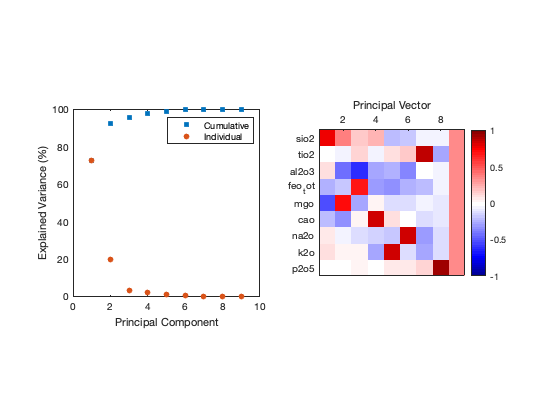

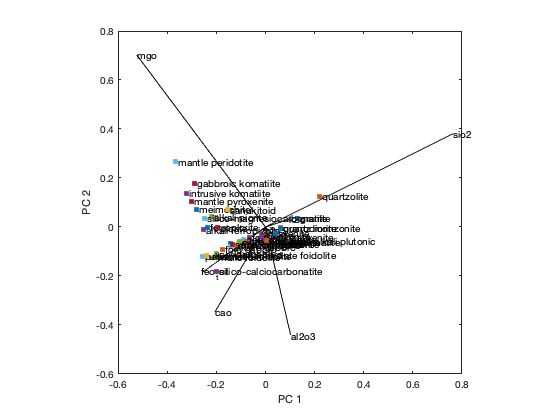

db_pca(data);

### 8.4.2 Relationship to SVD Decomposition

Singular value decomposition is a faster way to obtain PCA information.  Every matrix can be decomposed into the product of three matrices,


$${\bf X} = {\bf U S V}^\text{T}$$


where ${\bf U}$ and ${\bf V}$ are the unitary matrices which are rotations, ${\bf S$}$ is a diagonal matrix of singular values that creates a scaling factor.  Both ${\bf U}$ and ${\bf V}$ are constructed from unit vectors such that if both are real-valued, ${\bf U U}^\text{T} = {\bf I}$ and ${\bf V V}^\text{T} = {\bf I}$.  Using the definition of the covariance matrix, ${\bf \Sigma} = {\bf X}^\text{T}{\bf X}(N-1)^{-1}$,


$${\bf \Sigma} = {\bf V S U}^\text{T} {\bf U S V}^\text{T}(N-1)^{-1} = {\bf V}\frac{{\bf S}^2}{N-1}{\bf V}^\text{T}$$


Multiplying the right side of each by ${\bf V}$, we find


$${\bf \Sigma V} = {\bf V}\frac{{\bf S}^2}{N-1}$$


which is the eigenvalue decomposition if ${\bf V}$ is the matrix of principle components and ${\bf \Lambda} = \frac{{\bf S}^2}{N-1}$.

Returning to ${\bf X} = {\bf U S V}^\text{T}$, we can see that ${\bf \hat{X}} = {\bf U S}$ is the transformed dataset.

## 8.5 Multi-dimensional Scaling

Multidimensional scaling is a method that attempts to quantify the distances between samples as a measure of their similarity.  The distance between two samples can be quantified using one of the metrics discussed in Section 8.3. But rather than the true distance, the MDS distance is estimated from dimensionally reduced set of transformed variables—often of two or three coordinates so the result can be visualized. The results are then presented on a Cartesian plot where points that plot close together are more similar in characteristics than points that plot further away.

### 8.5.1 Classical MDS 

The classical MDS is basically PCA.  MDS can be reduced to a PCA in some cases as shown by the example below.  Consider the SVD decomposition of the centered data matrix ${\bf X}$,


$${\bf X} = {\bf U S V}^\text{T}$$


If we assume the sum of first two elements of ${\bf S}$ are much larger sum of all others, ${s_1 + s_2 \gg s_3 + \cdots + s_N$, then we can approximate the SVD as,

${\bf X} \approx \pmatrix{\bf U_1 & \bf U_2} \pmatrix{s_1 & 0 \cr 0 & s_2} \pmatrix{\bf V_1 & \bf V_2}^\text{T}$ ,

For the $i$-th sample, this becomes,

${\bf X_i} \approx \pmatrix{\bf U_1 & \bf U_2} \pmatrix{s_1 & 0 \cr 0 & s_2} \pmatrix{v_{i,1} \cr v_{i,2}} = \pmatrix{\bf U_1 & \bf U_2} \pmatrix{s_1 v_{i,1} \cr s_2 v_{i,2}}$ ,

we can then define a transformed 2-element set of coordinates—note these are simply the 1st and 2nd principle component scores,


$${\bf \hat{X}_i} = \pmatrix{s_1 v_{i,1} \cr s_2 v_{i,2}}$$


If we take the difference between two points ${\bf X_i}$ and ${\bf X_j}$, we can write this in terms of the 

transformed coordinates,


$${\bf X_i} - {\bf X_j} \approx \pmatrix{\bf U_1 & \bf U_2}({\bf \hat{X}_i - {\bf \hat{X}_j})$$


If we look at the squared deviations,


$$({\bf X_i} - {\bf X_j})^\text{T}({\bf X_i} - {\bf X_j}) \approx ({\bf \hat{X}_i} - {\bf \hat{X}_j})^\text{T} \pmatrix{\bf U_1 & \bf U_2}^\text{T}\pmatrix{\bf U_1 & \bf U_2}({\bf \hat{X}_i - {\bf \hat{X}_j})$$


which is simply,

$({\bf X_i} - {\bf X_j})^\text{T}({\bf X_i} - {\bf X_j}) \approx ({\bf \hat{X}_i} - {\bf \hat{X}_j})^\text{T} ({\bf \hat{X}_i - {\bf \hat{X}_j})$,

or more simply,

$d^2({\bf X_i},{\bf X_j}) \approx \hat{d}^2_{ij} = (\hat{X}_{1,i} - \hat{X}_{1,j})^2 + (\hat{X}_{2,i} - \hat{X}_{2,j})^2$ ,

where $d({\bf X_i},{\bf X_j})$ is the true multivariate distance and $\hat{d}_{ij}$ is the MDS approximated distance.  Of course you could include additional dimension to compute the distance.  For instance, for three dimensions, you would obtain,


$$d^2({\bf X_i},{\bf X_j}) \approx \hat{d}^2_{ij} = (\hat{X}_{1,i} - \hat{X}_{1,j})^2 + (\hat{X}_{2,i} - \hat{X}_{2,j})^2 + (\hat{X}_{3,i} - \hat{X}_{3,j})^2$$


% let's use the average chemistry that we computed for common rock types in
% the radar plot section
for i = 1:length(R.types)
    for j = 1:length(R.types)
        D(i,j) = sqrt(sum((R.vals(i,:) - R.vals(j,:)).^2));
    end
end

% find a configuration with those inter-point distances
[Y eigenvals] = cmdscale(D);

Dtriu = D(find(tril(ones(length(R.types)),-1)))';
maxrelerr = max(abs(Dtriu-pdist(Y(:,1:2))))./max(Dtriu)

maxrelerr = 0.0028

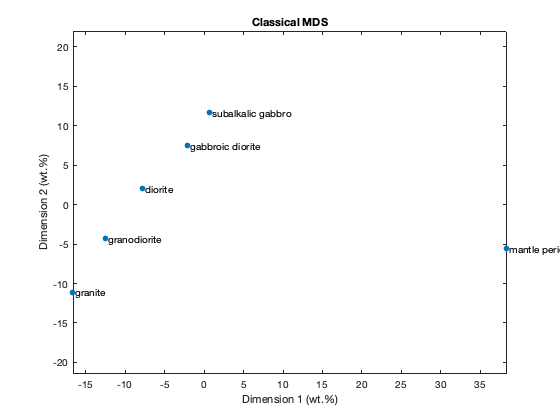

figure;
scatter(Y(:,1),Y(:,2),'o','filled')
text(Y(:,1)+0.3,Y(:,2),R.types)

xlabel('Dimension 1 (wt.%)');
ylabel('Dimension 2 (wt.%)');
title('Classical MDS');
set(gca,'Box','on');
axis equal;

The relative distances between points that result from classical MDS gives an estimate of the similarity (close) to dissimilarity (far) from each other on the plot.

### 8.5.2 Non-classical MDS

In the classical model, we approximate the observed distance by a dimensionally reduced transformed data,

$\hat{d}_{ij} \approx d_{ij} = ||{\bf X_i} - {\bf X_j}||_2$.

However, in the non-classical MDS, we wish to improve our distance estimate and incorporate qualitative (ordinal) data as well.  If all the data included in the analysis are quantitative, we perform metric MDS whereas if some or all of the data are qualitative, we perform a non-parametric MDS analysis.  We will change our distance approximation that we wish to minimize,


$$f(\hat{d}_{ij}) \approx d_{ij} =  ||{\bf X_i} - {\bf X_j}||_2$$


where $f(\hat{d}_{ij})$ is a monotonic function, e.g., $f(\hat{d}_{ij}) = m \hat{d}_{ij} + b$.  The function to minimize is called the stress (no relation to pressure) in MDS analysis,


$$\text{stress} = \left( \frac{\sum_{i<j} (d_{ij} - f(\hat{d}_{ij}))^2}{\sum_{i=1}^N \hat{d}_{ij}^2} \right)^{1/2}$$


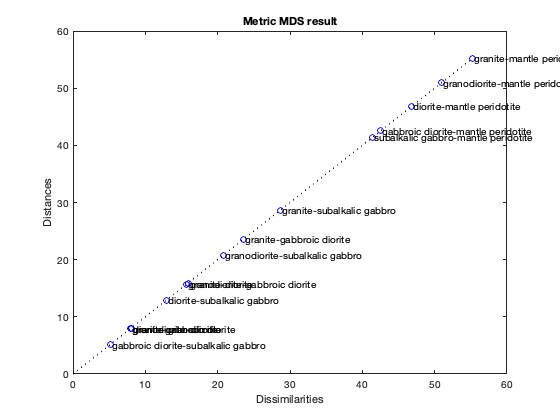

% let's use the average chemistry that we computed for common rock types in
% the radar plot section
dissimilarities = pdist(R.vals);

[Y,stress] = mdscale(dissimilarities,2,'criterion','metricsstress');
distances = pdist(Y);

figure;
plot(dissimilarities,distances,'bo', ...
    [0 max(dissimilarities)],[0 max(dissimilarities)],'k:');
k = 1;
for i = 1:length(R.types)
    for j = i+1:length(R.types)
        text(dissimilarities(k)+0.2,distances(k),[R.types{i},'-',R.types{j}])
        k = k + 1;
    end
end
xlabel('Dissimilarities');
ylabel('Distances')
title('Metric MDS result')

## 8.6 Linear Discriminant Analysis

PCA and MDS do not require the data to be divided into samples classes (e.g., rock types, site, species, etc.), thus providing a way to produce a score or distance from every point to every other point.  Using the average of each class as we did above we can obtain a metric for the differences between classes.  However, for unknown samples, it is perhaps not clear to which class the data should belong especially when there is overlap between the classes.  Linear discriminant analysis (LDA) allows one to separate samples based on the differences between the classes.  So imagine we collect a dataset with $M$ dimensions and $N$ samples.  The data can be subset into $K$ unique classes.

The first step to perform a LDA is to determine the mean of each dimension within each class, resulting in a vector $\mathbf{\bar{x}}_i$ and the $L_2$ distance between each sample within a class and the mean, which is called the scatter,


$$\mathbf{S_i} = (\mathbf{X}_i - \mathbf{1}_{n_i}^\text{T}\mathbf{\bar{x}}_i)^\text{T}(\mathbf{X}_i - \mathbf{1}_{n_i}^\text{T}\mathbf{\bar{x}}_i)$$


where $\mathbf{X}_i$ is the subset of $\mathbf{X}$ with class $i$, $n_i$ is the number of samples in class $i$, and $\mathbf{1}_{n_i}$ is a column vector of ones with length $n_i$.  $\mathbf{S}_i$ is simply the covariance matrix of class $i$.  The **within class scatter** (pooled covariance matrix) is given by the sum over each class,


$$\mathbf{S}_w = \sum_{i = 1}^K\mathbf{S}_i$$


We now need to know how the class averages vary with respect to each other.  We compute a quantity called the **between class scatter** (covariance matrix between the classes), which is computed using the mean of all the pooled data, $\mathbf{\bar{x}}$,


$$\mathbf{S}_b = \sum_{i=1}^K n_i (\mathbf{\bar{x}}_i - \mathbf{\bar{x}})^\text{T} (\mathbf{\bar{x}}_i - \mathbf{\bar{x}})$$


Now we wish to solve for the eigenvalues and eigenvectors of the system


$$\mathbf{S}_w^{-1}\mathbf{S}_b \mathbf{V} = \mathbf{\Lambda}\mathbf{V}$$


just as we would for PCA.  If you use the eig.m function in MATLAB, you can obtain both the eigenvalues and eigenvector matrix.  You can normalize the eigenvalues to 1, $\lambda_i (\sum_{i = 1}^{K} \lambda_i)^{-1}$, to obtain the explained variance for each eigenvector.

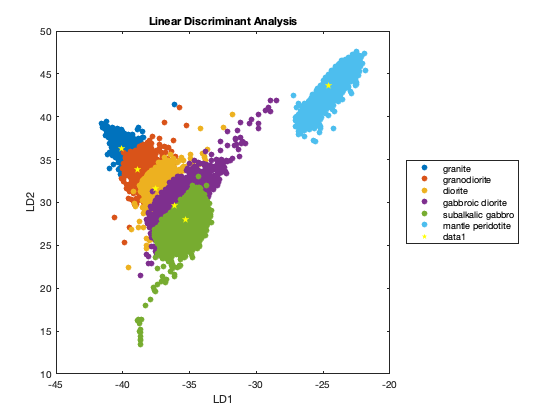

% MATLAB does not have a linear discriminant analysis function, but can the
% code below could be written to do so.

% columns of data to be used
oxides = {'sio2','tio2','al2o3','feo_tot','mgo','cao','na2o','k2o','p2o5'};

% rock types analyzed
% use all
%rock_types = unique(data.rock_type);
% use subset
rock_types = {'granite','granodiorite','diorite','gabbroic diorite','subalkalic gabbro','mantle peridotite'};

% create the vector of ones
one = ones([height(data),1]);

% initialize within and between class scatter matrices
Sw = zeros(length(oxides));
Sb = zeros(length(oxides));

% if only a partial list of rock types are analyzed
aind = zeros([height(data),1]);
for i = 1:length(rock_types)
    aind = aind | strcmp(data.rock_type,rock_types{i});
end

% mean of each column for all the data
datamean = one(aind)'*data{aind,oxides}/sum(aind);

% compute within and between class scatter matrices
for i = 1:length(rock_types);
    % find class i
    ind = strcmp(data.rock_type,rock_types{i});
    
    % number of samples in class
    ni(i) = sum(ind);
    
    % mean of columns in class subset of data
    classmean(i,:) = one(ind)'*data{ind,oxides}/ni(i);
    
    % covariance of class
    Si = (data{ind,oxides} - one(ind)*classmean(i,:))'*(data{ind,oxides} - one(ind)*classmean(i,:));
    % within class scatter matrix (total covariance)
    Sw = Sw + Si;
    
    % between class scatter matrix
    Sb = Sb + ni(i)*(classmean(i,:) - datamean)'*(classmean(i,:) - datamean);
end

% compute eigenvalues and eigenvectors
[V,D] = eig(inv(Sw)*Sb,'vector');

% compute explained variance
explained = D./sum(D);

figure;
hold on;
% plot the LD scores
for i = 1:length(rock_types);
    ind = strcmp(data.rock_type,rock_types{i});
    scatter(data{ind,oxides}*V(:,1),data{ind,oxides}*V(:,2),'o','filled');
end
legend(rock_types,'Location','EastOutside');

% plot mean of the classes
scatter(classmean*V(:,1),classmean*V(:,2),60,'yp','filled');
set(gca,'Box','on');
xlabel('LD1');
ylabel('LD2');
title('Linear Discriminant Analysis');

You will notice that the LDA result is significantly different than PCA because PCA finds the maximum similarity between samples whereas LDA tries to find the maximum differences.  The result is a better discrimination between classes.